# Pre-processing of 2-Lead ECG Data

close all
clear all

#### Load data

data_train = importdata("TwoLeadECG_TRAIN.txt");
data_train = sortrows(data_train);
data_test = importdata("TwoLeadECG_TEST.txt");
data_test = sortrows(data_test);

#### Separate labels and data

labels_train = data_train(:,1);
labels_train_dup = labels_train;
data_train(:,1)=[];

labels_test = data_test(:,1);
data_test(:,1)=[];

## Visualise some sample ECG time series

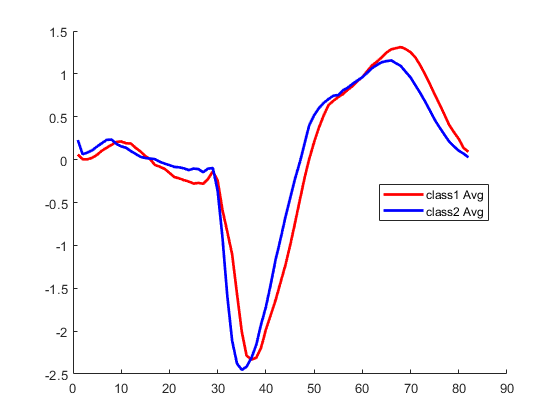

timeArray=1:82;

avg_1 = mean(data_train(1:12,:),1);
avg_2 = mean(data_train(13:23,:),1);

figure
hold on
plot(timeArray,avg_1,'r-','LineWidth',2)
plot(timeArray,avg_2,'b-','LineWidth',2)
hold off
legend("class1 Avg","class2 Avg", 'Location','best')

Visualise ECG Lead-1 in training dataset

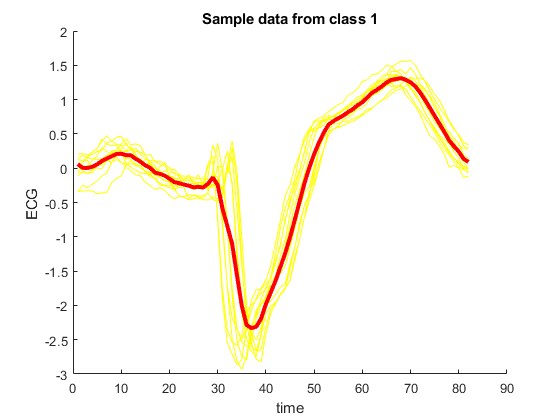

figure
hold on
plot(timeArray,data_train((1:11),:),'y-', "LineWidth",0.1)
plot(timeArray,avg_1,'r-','LineWidth',3)
hold off
title("Sample data from class 1")
xlabel("time")
ylabel("ECG ")

Visualise ECG Lead-2 in training dataset

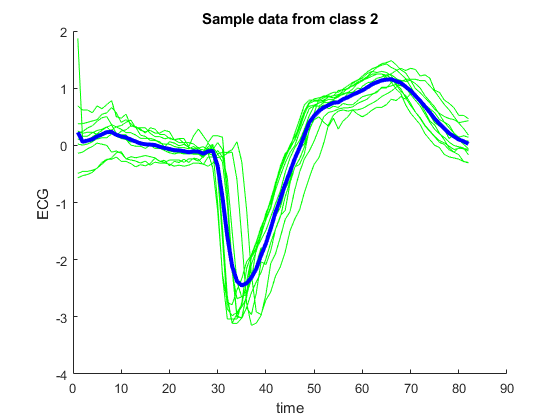

figure
hold on
plot(timeArray,data_train((13:23),:),'g-', "LineWidth",0.1)
plot(timeArray,avg_2,'b-','LineWidth',3)
hold off
title("Sample data from class 2")
xlabel("time")
ylabel("ECG ")

# Correlation

corr_matrix_train = corr(data_train'); dup = corr_matrix_train;
corr_matrix_test = corr(data_test');

#### Colour map of unthresholded test data

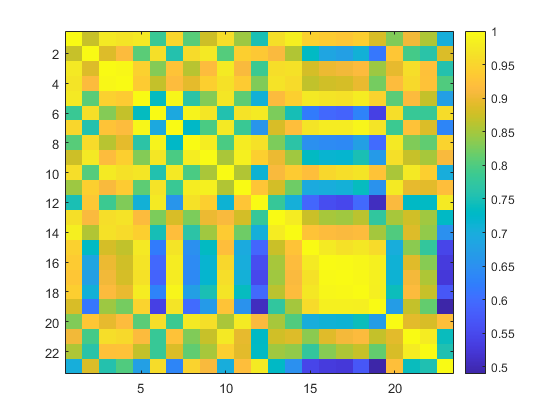

figure
imagesc(corr_matrix_train)
colorbar

#### Colour map of unthresholded training data

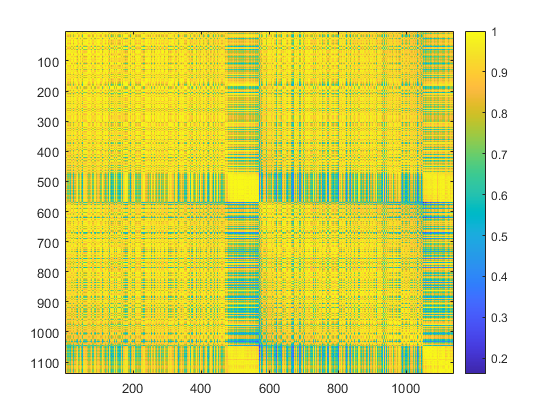

figure
imagesc(corr_matrix_test)
colorbar

# **Getting the threshold using modularity**

Plotting the modularity and diamter profile of the training data wrt threshold

th = 0:0.0001:0.98; diam =[]; Q = [];

for i = 1:length(th)
        dup = corr_matrix_train; % this is now our adj matrix
        dup = dup > th(i);
        diam = [diam, getDiameter(dup)];
        Q = [Q, getMod(dup, labels_train)];
end

Diameter profile

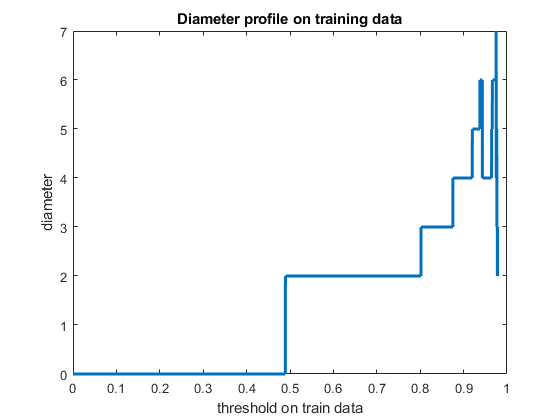

figure
plot(th, diam, "LineWidth",2)
title('Diameter profile on training data')
xlabel('threshold on train data')
ylabel('diameter')

Modularity profile

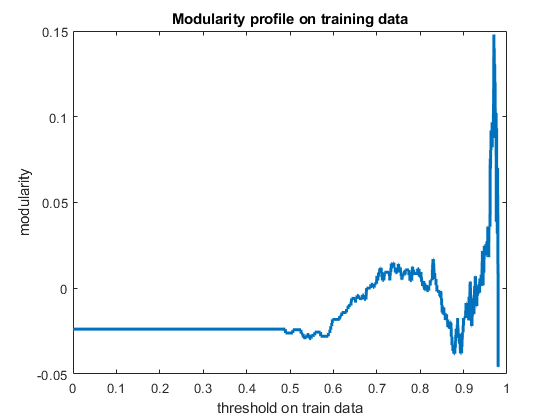

figure
plot(th,Q, "LineWidth",2)
title('Modularity profile on training data')
xlabel('threshold on train data')
ylabel('modularity')


figure
plot(th,log(Q), "LineWidth",2)

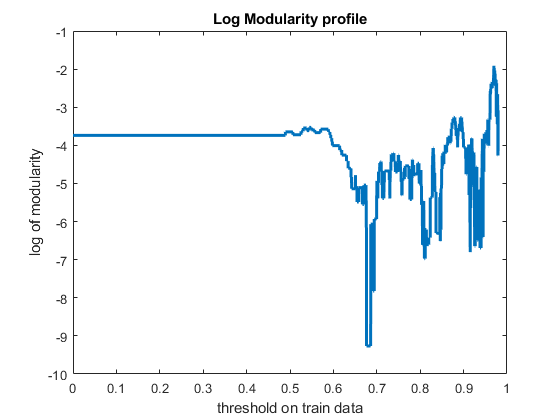

title('Log Modularity profile')
xlabel('threshold on train data')
ylabel('log of modularity')

From the modularity profile as a function of the correlation threshold, we get some idea about how the modularity is changing with linear correlation coeff. **The threshold is set as the correlation coeff corresponding  MAX of modularity**

threshold = min(th(find(Q==max(Q))))

threshold = 0.9697

#### Plot TRAIN data with the MAX modularity threshold

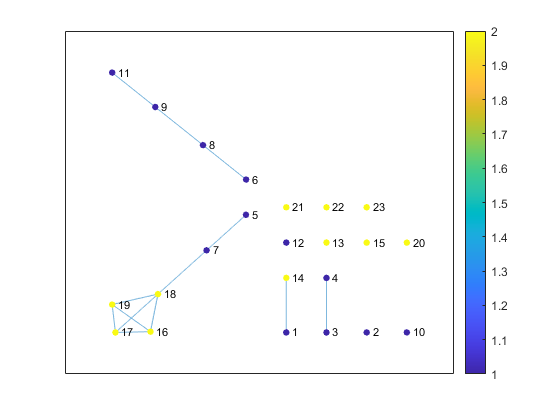

dup_train = corr_matrix_train > threshold;
G = graph(dup,'omitselfloops');

figure
plot(G,'NodeCData',labels_train)
colorbar


[~,binsize] = conncomp(G);
components = sort(binsize,"descend")

components =      6     4     2     2     1     1     1     1     1     1     1     1     1


diam_train = getDiameter(dup_train)

diam_train = 6

We can see that there is very poor class separation on the traing data with our modularity based thresholding method. We are getting a lot more than two communities. It is expected that we should get two communities as this is a two-class problem.

#### Plot TEST data with the modularity threshold

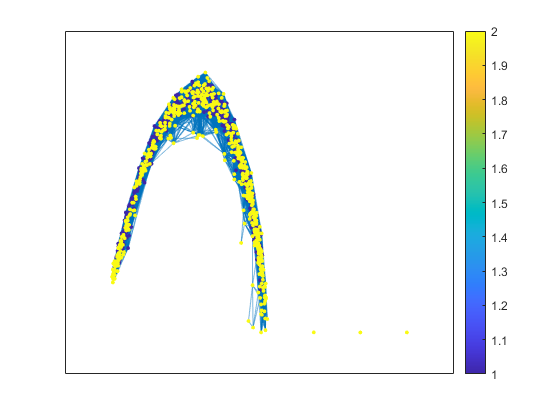

dup_test = corr_matrix_test > threshold;
Graph_test = graph(dup_test, 'omitselfloops');
figure
plot(Graph_test,'NodeCData',labels_test)
colorbar

Because of the bad thresholding from the training data, we failed to get good classification on our test data

#### Colour map of TRAIN adj mat

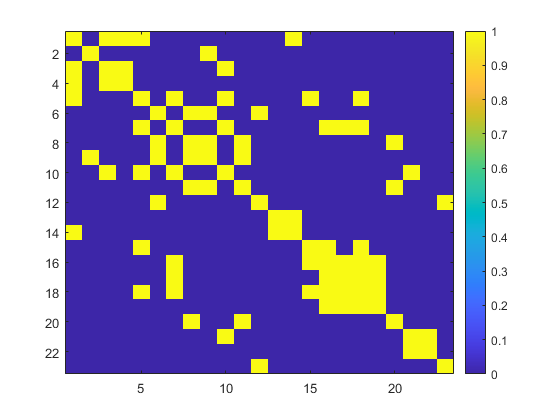

figure
imagesc(dup_train)
colorbar

#### Colour map of TEST adj mat

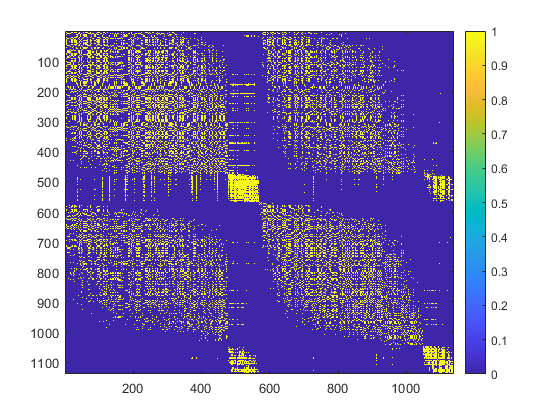

figure
imagesc(dup_test)
colorbar

# Another way to get a correlation threshold, is to break the loop when modularity reaches an acceptable value

The modularity value was set arbitrarily by looking at the modulaity profile of training data

set_mod_thresh = 0.05

set_mod_thresh = 0.0500

We break the loop when the set modularity is achieved and take the corresponding correlation coeff as our threshold for the test corr matrix

for i = 1:length(th)
        dup = corr_matrix_train; % this is our adj matrix
        dup = dup > th(i);
        Q = [Q, getMod(dup, labels_test)];
        if Q(i)> set_mod_thresh
                thresh_value = th(i);
                break
        end
end

We thus obtain a threshold from our training data whuch can be used on the test data

threshold = thresh_value

threshold = 0.9611

#### Plot TRAIN data with the modularity threshold

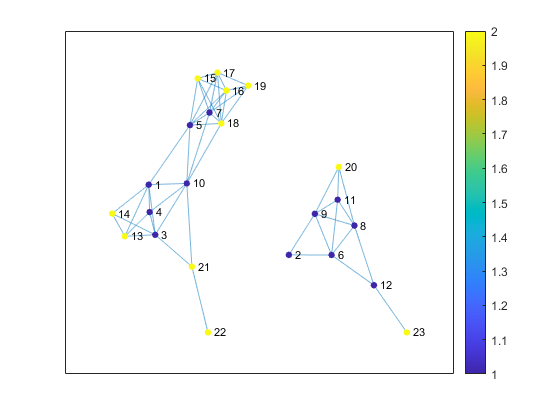

dup_train = corr_matrix_train > threshold;
G = graph(dup,'omitselfloops');

figure
plot(G,'NodeCData',labels_train)
colorbar


[~,binsize] = conncomp(G);
components = sort(binsize,"descend")

components =     15     8


diam_train = getDiameter(dup_train)

diam_train = 4

We can see that there is very poor class separation on the traing data with our modularity based thresholding method. But we are getting two communities. It is expected that we should get two communities as thisa two class problem. **Therefore, this method is better than the MAX modularity method.**

#### Plot TEST data with the modularity threshold

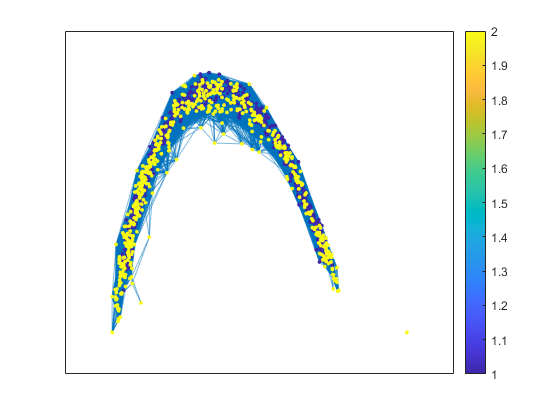

dup_test = corr_matrix_test > threshold;

Graph_test = graph(dup_test, 'omitselfloops');
figure
plot(Graph_test,'NodeCData',labels_test)
colorbar

Because of the bad thresholding from the training data, we failed to get good classification on our test data

#### Colour map of TRAIN adj mat

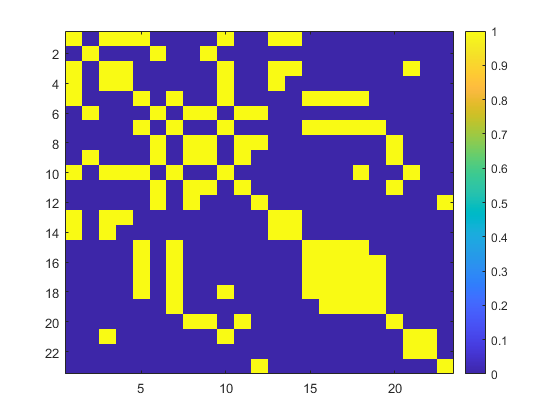

figure
imagesc(dup_train)
colorbar

#### Colour map of TEST adj mat

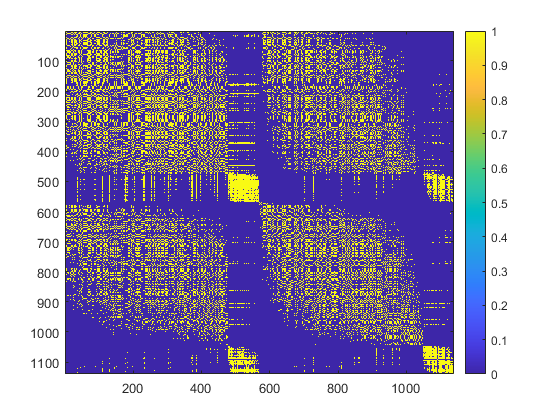

figure
imagesc(dup_test)
colorbar

# **Getting the threshold using connected components**

threshold = 1;
dup = dup > threshold;
G = graph(dup,'omitselfloops');
[bin,binsize] = conncomp(G);

We run a loop until the number of communities is 2 i.e, two classes are separated. This is accomplisjed by checking the connected components.

while length(binsize) > 2
        dup = corr_matrix_train;
        dup = dup > threshold;
        G = graph(dup);
        [bin,binsize] = conncomp(G);
        threshold = threshold - 0.0001;
end


#### Plot TRAIN data with the threshold

threshold

threshold = 0.9749

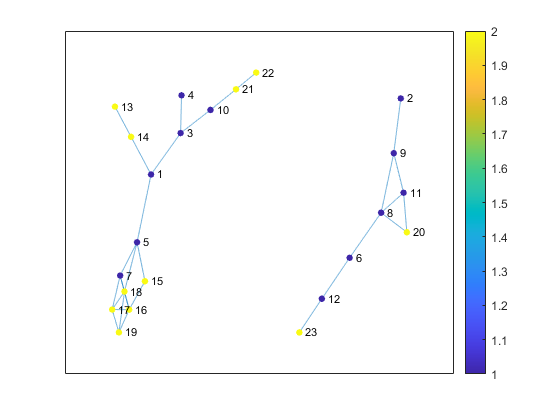

dup_train = corr_matrix_train > threshold;
G = graph(dup_train,'omitselfloops');

figure
plot(G,'NodeCData',labels_train)
colorbar


[bin,binsize] = conncomp(G);
components = sort(binsize,"descend")

components =     15     8


#### Plot TEST data with same threshold

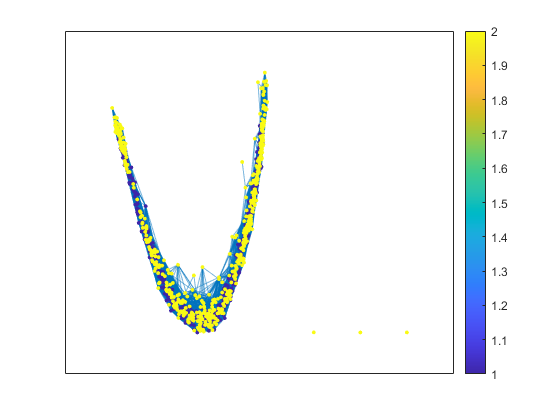

dup_test = corr_matrix_test > threshold;

Graph_test = graph(dup_test, 'omitselfloops');
figure
plot(Graph_test,'NodeCData',labels_test)
colorbar

This method yeild similar results as the previous method of modularity based thresholding withig loop break. The threshold values are also comparable.

#### Colour map of test adj mat

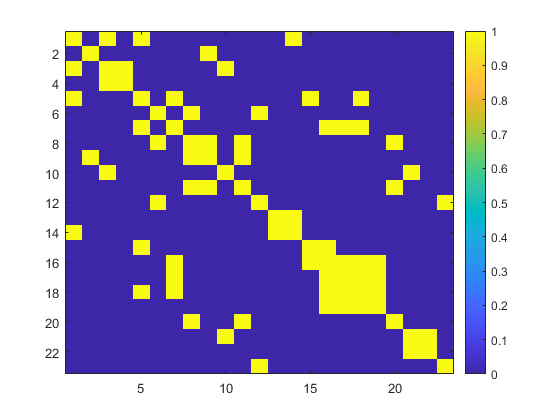

figure
imagesc(dup_train)
colorbar

#### Colour map of training adj mat

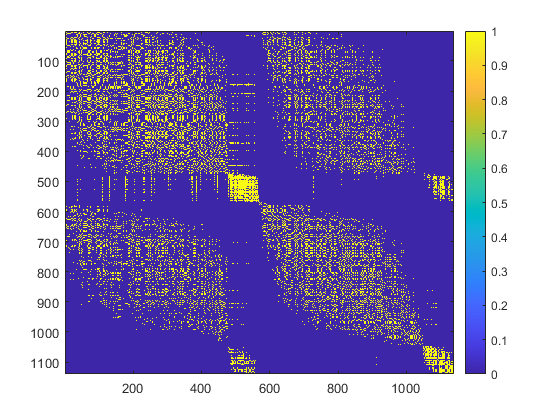

figure
imagesc(dup_test)
colorbar

# **Identifying interesting features of the ECG data from clusters**

data_test = importdata("TwoLeadECG_TEST.txt");
data = sortrows(data_test);
labels = data(:,1);
data(:,1)=[];
threshold

threshold = 0.9749

#### Dense Cluster around 500

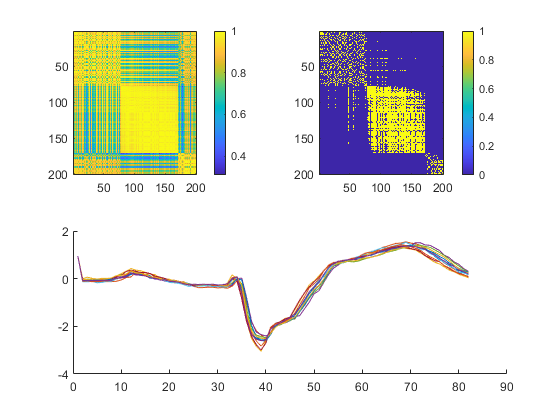

part = data(400:600,:); corr_part = corr(part');
LowerLimit = 500; UpperLimit = 510;

figure
subplot(2,2,1);
imagesc(corr_part)
colorbar

subplot(2,2,[3,4]);
hold on
for i = LowerLimit:UpperLimit
        plot(timeArray,data(i,:))
end
hold off

subplot(2,2,2);
corr_part = corr_part > threshold;
imagesc(corr_part)
colorbar

#### Dense Cluster around 1100

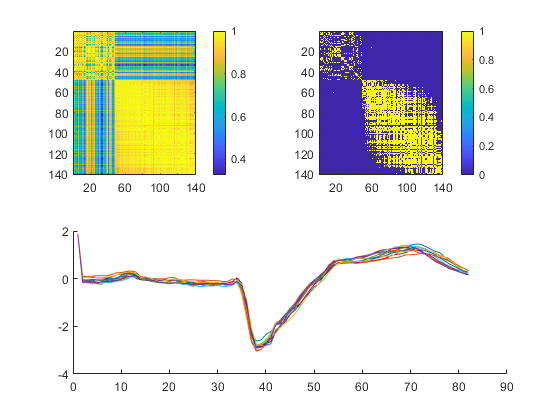

part = data(1000:end,:);corr_part = corr(part');
LowerLimit = 1100; UpperLimit = 1110;

figure
subplot(2,2,1);
imagesc(corr_part)
colorbar

subplot(2,2,[3,4]);
hold on
for i = LowerLimit:UpperLimit
        plot(timeArray,data(i,:))
end
hold off

subplot(2,2,2);
corr_part = corr_part > threshold;
imagesc(corr_part)
colorbar

For the two dense clusters shown above (region around 500 and region around 1100), the subplots on the top show the correlation matrix and the subplot on the bottom shows a sample of 10 time series data in that general region. We can see that the high correlation coefficients in the matrix corresponds to high similarity between the ECG waveforms.

#### Sparse Cluster around 700 - 1100

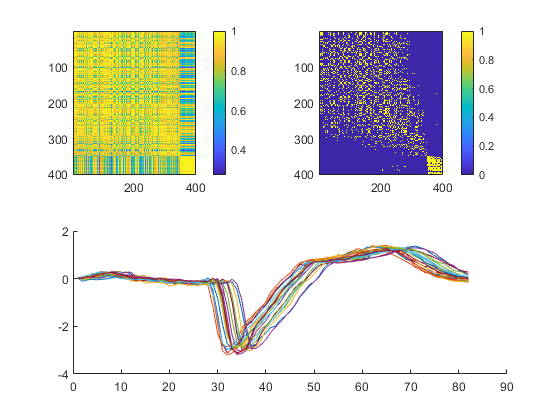

part = data(700:1100,:);corr_part = corr(part');
LowerLimit = 810;UpperLimit = 830;

figure
subplot(2,2,1);
imagesc(corr_part)
colorbar

subplot(2,2,[3,4]);
hold on
for i = LowerLimit:UpperLimit
        plot(timeArray,data(i,:))
end
hold off

subplot(2,2,2);
corr_part = corr_part > threshold;
imagesc(corr_part)
colorbar

For the figure shown above (region 700 - 1100), the subplots on the top show the correlation matrix and the subplot on the bottom shows a sample of 30 time series data in that general region. This is indeed a sparse cluster. We can see that the low correlation coefficients (indicated by blue puncta) in the matrix corresponds to low similarity between the ECG waveforms. 

%WOrking on test data distances
distG = []


distG =

     []



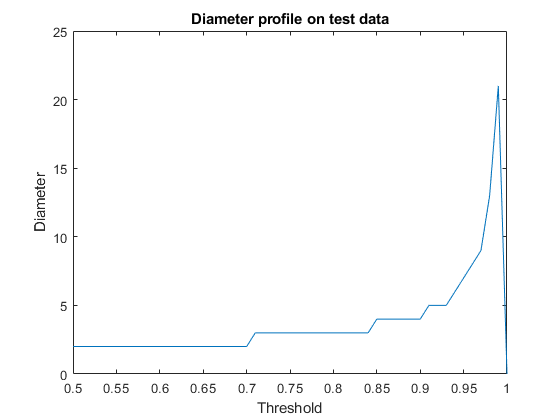

for thresh=0.5:0.01:1
    dup = corr_matrix_test > thresh;
    dist = distances(graph(dup));
    dist(dist==Inf)=-1;
    distG = [distG max(max(dist))];
end

figure()
plot(0.5:0.01:1,distG);
title("Diameter profile on test data");
xlabel("Threshold");
ylabel("Diameter")

Node centraility on the Giant Component on some thresholds

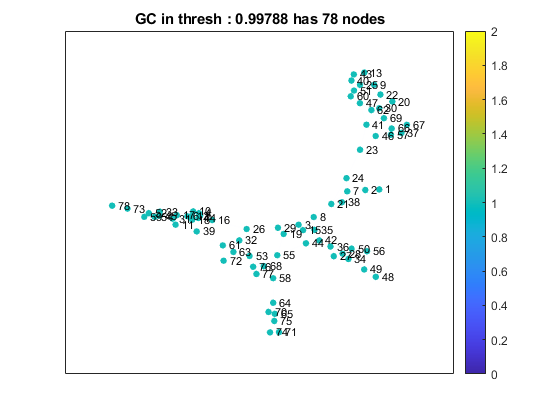

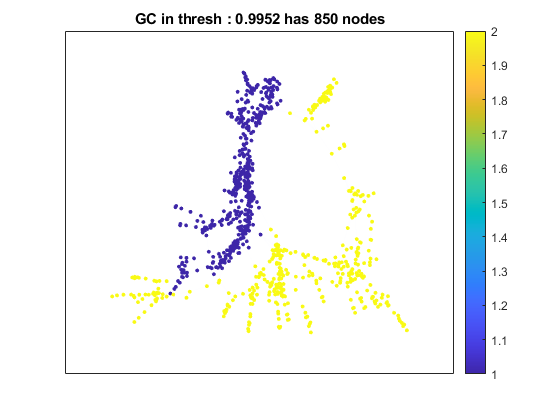

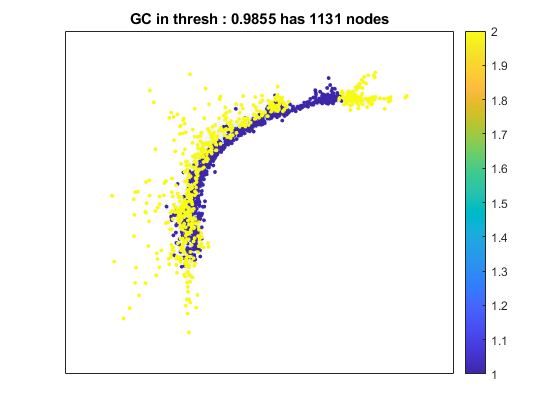

interesting_thresh = [0.99788, 0.9952, 0.9855];
centrality_across_thresh = zeros(1:length(size(data_test,1)));

for i = 1:length(interesting_thresh)
    dup_test = corr_matrix_test > interesting_thresh(i);
    Graph_test = graph(dup_test, 'omitselfloops');
    [bins, binsize] = conncomp(Graph_test);
    [Amnt,Pos_of_GC] = max(binsize);
    Index_of_GC = (bins==Pos_of_GC);
    Reduced_Graph = dup_test(Index_of_GC,Index_of_GC);
    Giant_Component = graph(Reduced_Graph, 'omitselfloops','upper');
    
    centrality_across_thresh = centrality_across_thresh + centrality(Graph_test,'degree')';
    
    %reduced_graph = graph(dup_test(x,Index_of_GC)) 
    figure
    
    p = plot(Giant_Component,'Layout','force','EdgeAlpha',0.005,'NodeCData',labels_test(Index_of_GC));
    title("GC in thresh : "+interesting_thresh(i)+" has "+Amnt+" nodes");
    colorbar
end